freq = [
100
200
300
400
500
600
700
800
900
1000
1250
1500
1750
2000
2250
2500
2750
3000
3250
3500
3750
4000
4250
4500
4750
5000
];

vout = [
0.052
0.148
0.16
0.132
0.124
0.144
0.144
0.204
0.224
0.18
0.284
0.352
0.332
0.408
0.41
0.42
0.42
0.54
0.652
0.656
0.74
0.76
0.8
0.82
0.79
0.62  
];

vin = [
0.52
0.84
1.04
0.72
0.82
1
0.72
1.04
1
0.8
0.8
0.84
0.84
0.92
0.88
0.88
0.94
1
1.04
1.04
1.1
1.1
1.1
1.1
1.1
1.1 
];

phase = [
-83.2
-143.9
-165
-171.36
-181.82
-164.9
-165
-172.32
-174.06
-176.36
-195
-217.7
-241.6
-253.2
-262.7
-285
-294
-304
-323
-348
-367
-390
-420
-445
-474.4
-510 
];

tran = vout./vin;

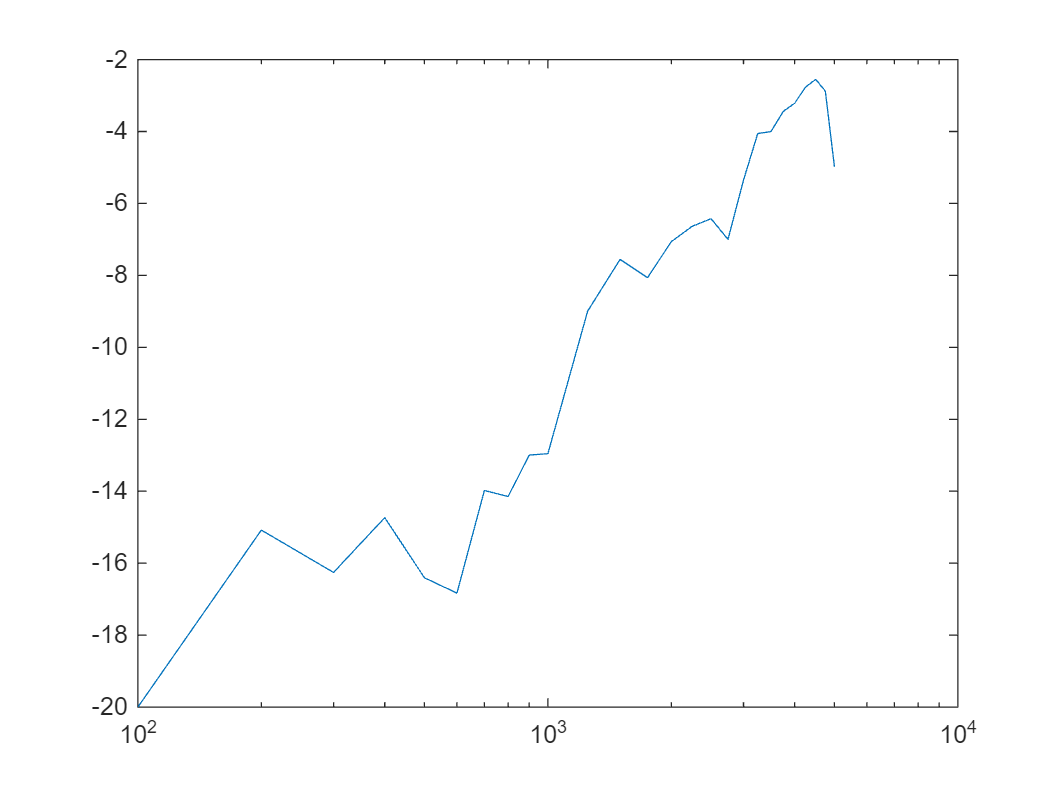

semilogx(freq, 20*log10(tran));

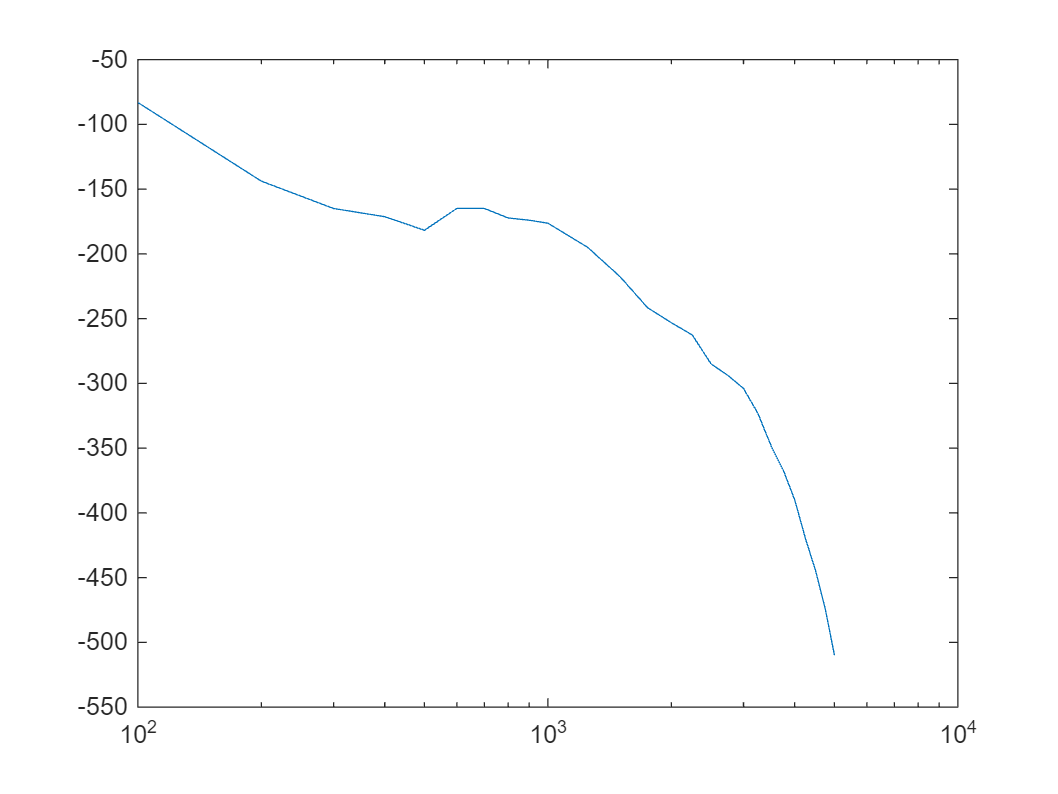

semilogx(freq, phase);

response = tran.*exp(1i*phase*pi/180);
Ts = 4*1e-5; % your sampling time
w=freq*2*pi; %convert Hz to rad/sec 

gfr = idfrd(response,w,Ts);

G=tfest(gfr,2);

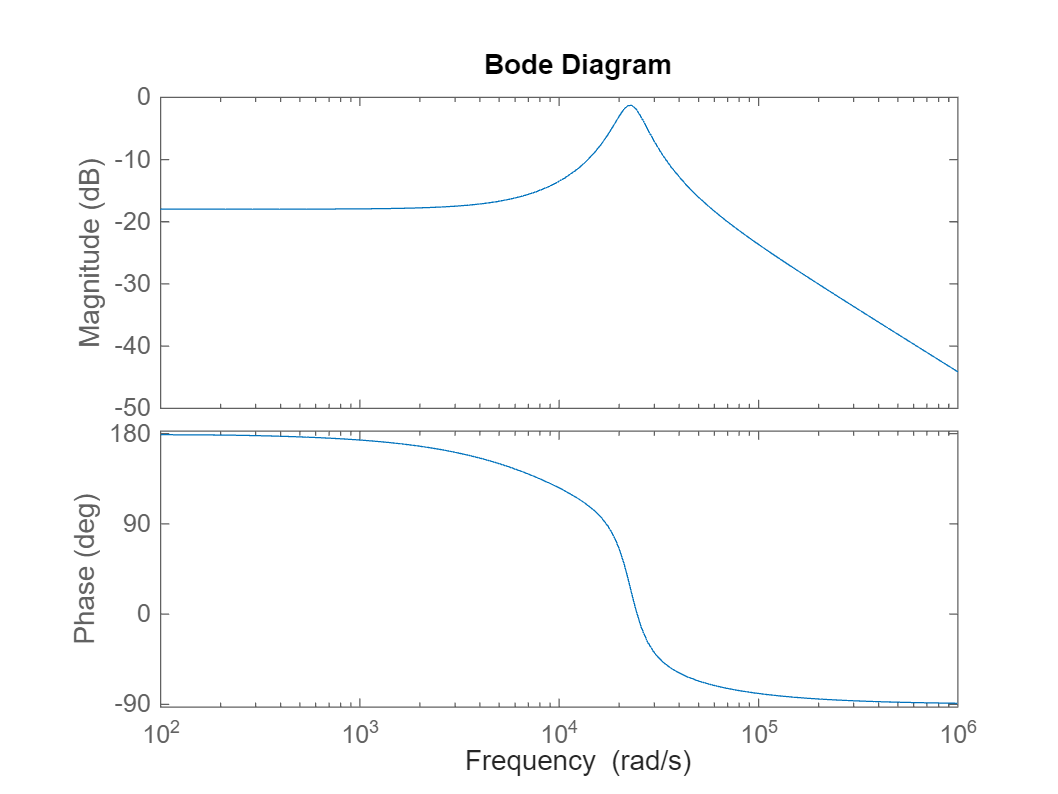

bodeplot(G)

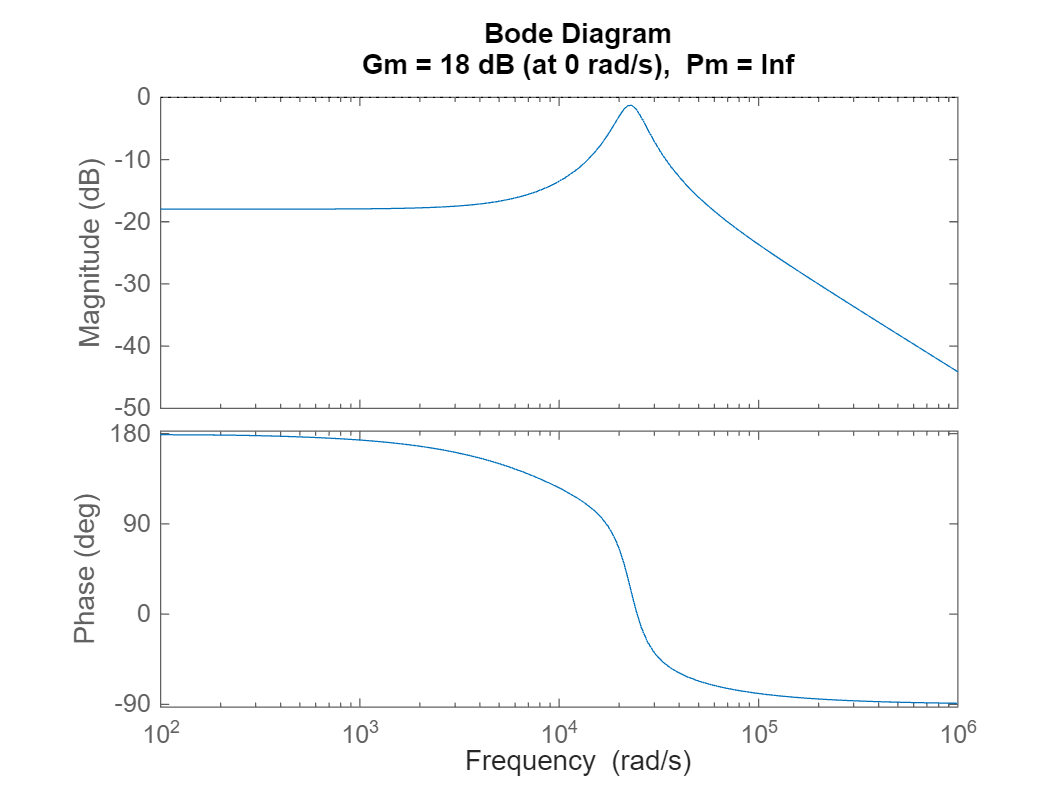

margin(G)

k = 1/162;
a = 27;
b = 162;
c = 25;
d = 100;
k = 100*((2*pi*100)^2+c*(2*pi*100)+d)/((2*pi*100)^2+a*(2*pi*100)+b)

k = 99.6799

comp = k*tf([1 a b], [1 c d]);

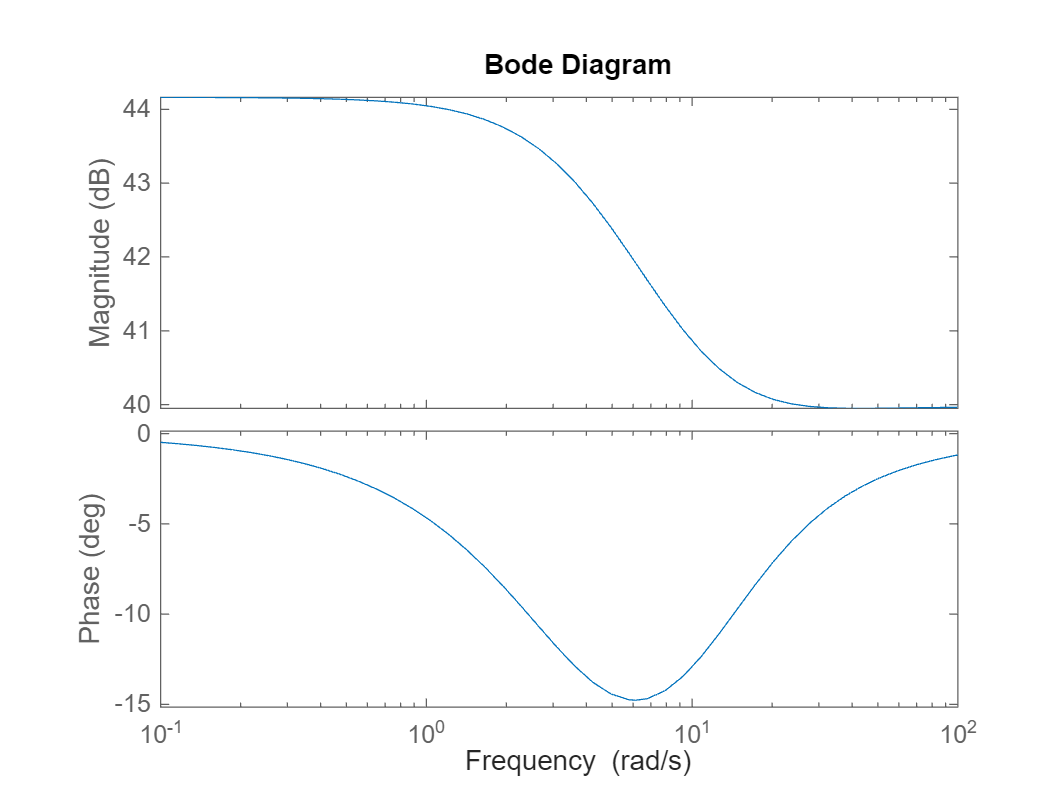

bodeplot(comp)

comp_sys = G*comp;
comp_sys_inclosedloop = comp_sys/(1 + comp_sys);
val = 20*log10(abs(evalfr(comp_sys,2*3.14*100*1j)));

val

val = 22.0125

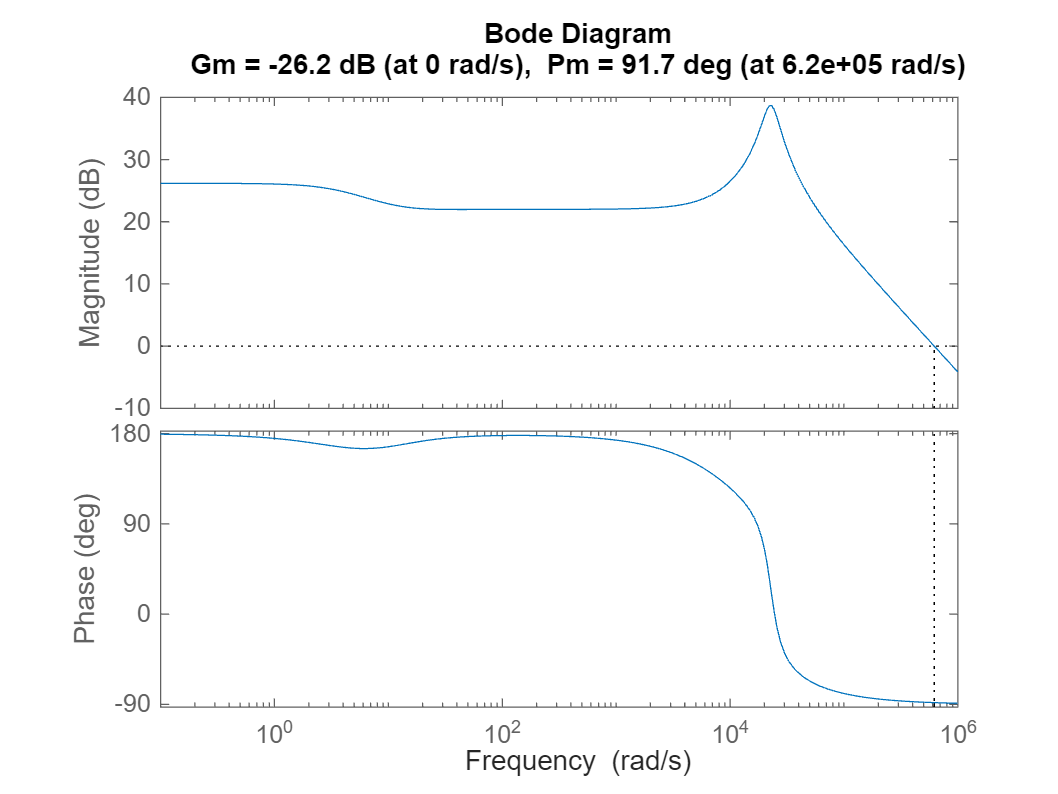

margin(comp_sys);

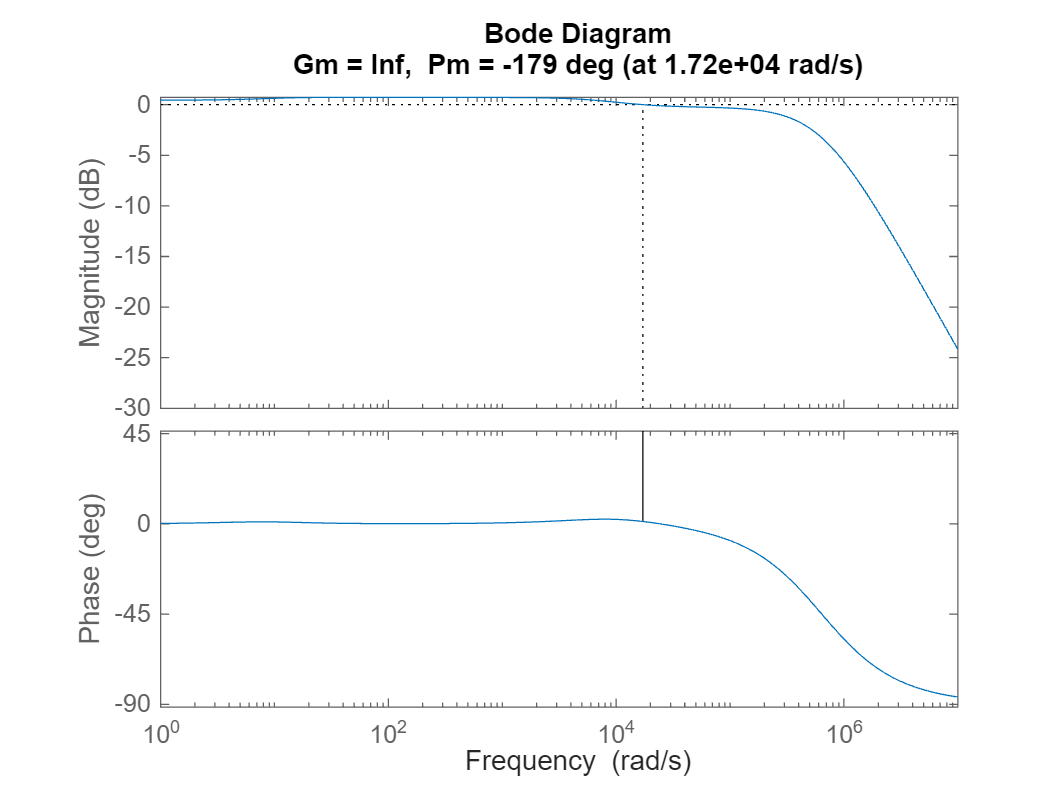

margin(comp_sys_inclosedloop)